clc
clear 


W2S=linspace(0,350,351);
sigma=0.0237/0.0765   %air density at 35000ft/sea level air density

sigma = 0.3098

M=0.7   %mach

M = 0.7000

alpha=(0.568+0.25*(1.2-M)^3)*(sigma^0.6)

alpha = 0.2967


R=1400*5280   %ft range

R = 7392000

C=0.595   %lb/lbf*hr fuel comsumption coefficient

C = 0.5950

V=462*5280   %ft/hr    

V = 2439360

l2d=15  %lift to drag

l2d = 15

beta=exp(-R*C/(V*(l2d)))

beta = 0.8867


e=0.8

e = 0.8000

AR=8.5

AR = 8.5000

K1=1/(pi*e*AR)

K1 = 0.0468


Cd0=0.02417

Cd0 = 0.0242


d=0.0237   %lbs/ft3 air density at 35000ft

d = 0.0237

v=462*5280/3600   %ft/s

v = 677.6000

q=(d*(v^2)/2)/(9.8*3.28)   %lb/ft2

q = 169.2642


%Constant Altitude/Speed Cruise
T2W_cruise=(beta/alpha)*((K1*(beta/q)*W2S)+Cd0./((beta/q)*W2S))

T2W_cruise =        Inf   13.7913    6.8967    4.5991    3.4506    2.7618    2.3028    1.9752    1.7297    1.5389    1.3864    1.2617    1.1580    1.0703    0.9953    0.9304    0.8736    0.8237    0.7793    0.7397    0.7042    0.6721    0.6430    0.6164    0.5922    0.5699    0.5495    0.5306    0.5130    0.4968    0.4817    0.4676    0.4544    0.4421    0.4305    0.4197    0.4095    0.3998    0.3908    0.3822    0.3741    0.3664    0.3591    0.3522    0.3457    0.3394    0.3335    0.3279    0.3225    0.3174



%constant speed climb 
dhdt=180000  %ft/hr 

dhdt = 180000

beta_climb=0.9752   %experience

beta_climb = 0.9752

V_climb=V*0.8

V_climb = 1951488

T2W_climb=(beta_climb/alpha)*(K1*(beta_climb/q)*W2S+Cd0./((beta_climb/q)*W2S)+(1/V_climb)*(dhdt))

T2W_climb =        Inf   14.0946    7.2003    4.9027    3.7544    3.0658    2.6070    2.2795    2.0341    1.8435    1.6911    1.5666    1.4631    1.3755    1.3007    1.2359    1.1793    1.1295    1.0853    1.0459    1.0105    0.9785    0.9496    0.9232    0.8991    0.8770    0.8567    0.8379    0.8206    0.8045    0.7895    0.7755    0.7625    0.7504    0.7390    0.7283    0.7182    0.7087    0.6998    0.6914    0.6834    0.6759    0.6688    0.6620    0.6556    0.6496    0.6438    0.6383    0.6331    0.6281



%Constant altitude turn
sita=pi/6   %rad

sita = 0.5236

V_turn=200   %knots

V_turn = 200

V_turn2=200*1.852/3.6/0.3048   %ft/s

V_turn2 = 337.5620

Rc=V_turn^2/(11.26*tan(sita))   %ft

Rc = 6.1529e+03

g=9.8*3.28   %ft

g = 32.1440

n=(1+(V_turn2^2/(g*Rc))^2)^0.5

n = 1.1541

beta_turn=0.6817

beta_turn = 0.6817


T2W_turn=(beta_turn/alpha)*(K1*(n^2)*(beta_turn/q)*W2S+Cd0./((beta_turn/q)*W2S))

T2W_turn =        Inf   13.7911    6.8964    4.5986    3.4499    2.7610    2.3019    1.9741    1.7284    1.5375    1.3848    1.2600    1.1561    1.0683    0.9931    0.9280    0.8711    0.8210    0.7765    0.7368    0.7011    0.6688    0.6395    0.6129    0.5885    0.5660    0.5454    0.5263    0.5087    0.4923    0.4770    0.4627    0.4494    0.4369    0.4252    0.4142    0.4038    0.3941    0.3848    0.3761    0.3678    0.3600    0.3526    0.3455    0.3388    0.3324    0.3263    0.3205    0.3150    0.3097



%Takeoff Ground Roll
beta_to=0.9801

beta_to = 0.9801

CLmax=3

CLmax = 3

V_stall=235   %ft/s C5 stall speed 

V_stall = 235


d_to=0.002377   %slug/ft3

d_to = 0.0024


T2W_takeoff=((2*beta_to)/(d_to*(V_stall^2)*CLmax)*W2S).^0.5

T2W_takeoff =          0    0.0706    0.0998    0.1222    0.1411    0.1578    0.1728    0.1867    0.1996    0.2117    0.2231    0.2340    0.2444    0.2544    0.2640    0.2732    0.2822    0.2909    0.2993    0.3075    0.3155    0.3233    0.3309    0.3384    0.3456    0.3528    0.3597    0.3666    0.3733    0.3799    0.3864    0.3928    0.3991    0.4053    0.4114    0.4174    0.4233    0.4291    0.4349    0.4406    0.4462    0.4518    0.4572    0.4626    0.4680    0.4733    0.4785    0.4837    0.4888    0.4939



%landing
Mff=0.5822   %from last report

Mff = 0.5822

V_landing=235   %ft/s C5 landing speed 

V_landing = 235


W2S_landing=(d_to*V_landing^2*CLmax)/2/Mff

W2S_landing = 338.2081

T2W=0:1:150;
W2S_landing2=W2S_landing*ones(size(T2W));

%service ceiling
sigma_ceiling=0.0149/0.0765

sigma_ceiling = 0.1948

alpha_ceiling=(0.568+0.25*(1.2-M)^3)*(sigma_ceiling^0.6)   %lbs/ft3 air density at 45000ft

alpha_ceiling = 0.2246

T2W_ceiling=(beta/alpha_ceiling)*((K1*(beta/q)*W2S)+Cd0./((beta/q)*W2S))

T2W_ceiling =        Inf   18.2197    9.1113    6.0758    4.5586    3.6486    3.0423    2.6095    2.2851    2.0330    1.8316    1.6669    1.5299    1.4140    1.3149    1.2291    1.1542    1.0882    1.0296    0.9773    0.9303    0.8879    0.8494    0.8144    0.7824    0.7530    0.7259    0.7009    0.6778    0.6563    0.6363    0.6177    0.6003    0.5840    0.5688    0.5544    0.5409    0.5282    0.5162    0.5049    0.4942    0.4841    0.4745    0.4653    0.4567    0.4484    0.4406    0.4331    0.4260    0.4193




%% plot with color on
A_1=area(W2S,T2W_cruise);
A_1.FaceAlpha=0.2;
hold on
A_2=area(W2S,T2W_climb);
A_2.FaceAlpha=0.2;
A_3=area(W2S,T2W_turn);
A_3.FaceAlpha=0.2;
A_4=area(W2S,T2W_takeoff);
A_4.FaceAlpha=0.2;
%A_5=area(W2S_landing2,T2W);
%A_5.FaceAlpha=0.2;
A_6=patch([W2S_landing 350 350 W2S_landing],[0 0 2 2],'cyan')

A_6 =   handle to deleted Patch


A_6.FaceAlpha=0.1

A_6 =   handle to deleted Patch


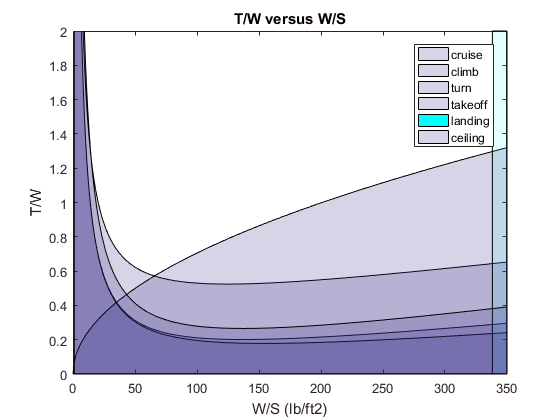

A_7=area(W2S,T2W_ceiling);
A_7.FaceAlpha=0.2;
hold off
legend('cruise','climb','turn','takeoff','landing','ceiling')
ylim([0 2])
xlim([0 350])

title('T/W versus W/S')
xlabel('W/S (lb/ft2)')
ylabel('T/W')

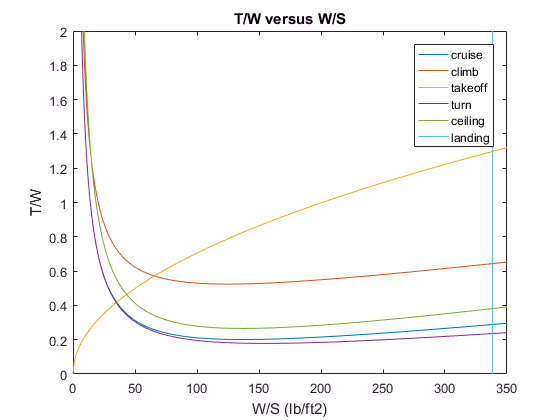



%% plot for line only
plot(W2S,T2W_cruise);
hold on

plot(W2S,T2W_climb);
plot(W2S,T2W_takeoff);
plot(W2S,T2W_turn);
plot(W2S,T2W_ceiling);
plot(W2S_landing2,T2W);

hold off
legend('cruise','climb','takeoff','turn','ceiling','landing' )
ylim([0 2])
title('T/W versus W/S')
xlabel('W/S (lb/ft2)')
ylabel('T/W')



%SG
%SG=(beta_to/alpha)*W2S_to*(V^2)/(2*g)   %ft

%SR
%SR=tR*kTO*((2*beta/(d*CLmax))*W2S)

%Sobs
%thetaobs=acos(1-hobs/Rc)
%hobs=
%Rc=
%VTO=
%go=
%Sobs=(((VTO^2)*sin(thetaobs))/(go*(0.8*(kTO)^2-1)))




